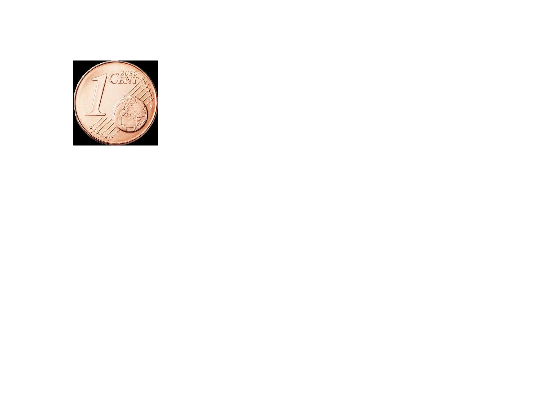

% Mehr Daten generieren
iterations = 1000;
for i = 1:8
    path = generateTestData(i-1, iterations);
    subplot(2,4,i);
    imshow(imread(path));
end

% Laden und Labeln
datasetPath = 'Dataset/';
imds = imageDatastore(datasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Unterteilen in Trainings- und Validierungsdaten
numTrainFiles = 750;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, 'randomized');

% Netzwerkarchitektur definieren
inputSize = [256 256 3];
numClasses = 8;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

% Netzwerk trainieren
options = trainingOptions('sgdm', 'MaxEpochs', 4,'ValidationData', imdsValidation, ...
    'ValidationFrequency', 30, 'Verbose', false, 'Plots', 'training-progress');

net = trainNetwork(imdsTrain, layers, options);

% Netzwerk testen
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

function origPath = generateTestData(index, iterations)
    rng(0, 'twister');
    path = sprintf('Dataset/%01d/', index);
    origPath = strcat(path, 'orig.jpg');
    I = imresize(imread(origPath), [256 256]);
    imwrite(I, origPath, 'jpg');

    for i = 1:iterations
        angle = randi([0, 359],1,1);
        In = imrotate(I, angle);
        
        targetSize = [256 256];
        win = centerCropWindow2d(size(In), targetSize);
        In = imcrop(In, win);

        str = fullfile(path,  sprintf('generatedData_%03d.jpg', i));
        imwrite(In, str, 'jpg');
    end
end